## Nanobots metrics evaluation

## Description

This file is the postprocessing Matlab code to compute two metrics: the traveling time per nanosensor and the concentration level of those along vessels in the human circulatory system (HCS). This code reads the CSV file provided by BloodvoyagerS, where the vessel ID per nanosensor along time is used to compute the two metrics. 

The traveling time represents the time in seconds per nanosensor to complete a closed circuit, those starting and ending at the right ventricle in the Heart. For example, a closed circuit is given by the traveling path from the left Heart to the tissues in the spleens (through the arteries) and the return to the left Heart (through the veins), see Fig. 1.

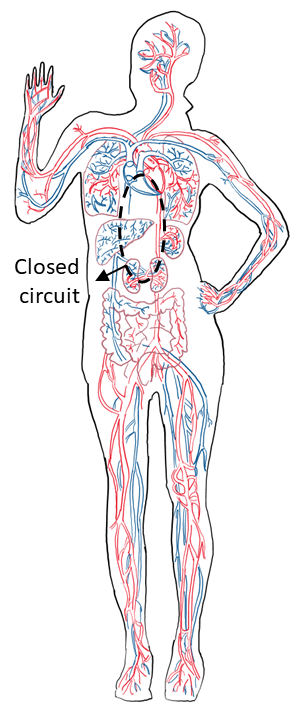

Fig. 1: Closed circuit representation in the HCS.

The concentration level represents the total of nanosensors per vessel ID reported per nanosensor. For example, when a given nanosensor travels through a vessel segment (e.g., Arcus Aortha, Thoracic Aorta), it will report the total of nanosensors in the same vessel segment. In the case depicted in Fig. 2, each nanosensor will report a total of 5 on the represented vessel segment.

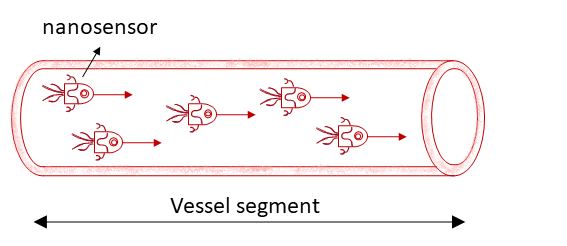

Fig. 2: Representation of flowing nanosensors in a given vessel segment.

A csv file from BVS should be located in the root folder to run this code. In this case, the file 'csvNano_1000bots_500s.csv' is available from the simulator, where 1000 nanosensors are deployed over 500 seconds. The file is organized in four main sections for the code:

- Loading data: This block loads the csv file as a table in Matlab

- Reading data: This block reads data from the table to store the traveling vessel ID per nanosensor.

- Computing: This block computes the traveling time along the closed circuit and the concentration level.

- Plotting: This block plots the resulting metrics traveling time and concentration level.

## Code

clc
clear
close all

### Loading data

**Description: **This block loads the first and sixth columns from the CSV table according to the bot ID and its traveling vessel ID. In the table, the data is given per bot per simulation time in rows, see Fig. 3. The columns are referred to the following items

- bot ID: integer value to distinguish the nanosensor.

- x, y, z: floating coordinates referred to the nanosensor location in the HCS, 

- time: integer value referred to the simulation time in the units of seconds,

- vessel ID: integer value referred to the vessel identification in the HCS. A description of vessel ID vs vessel nomenclature can be found in [this link](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf).

- stream ID: integer value to distinguish the traveling stream where the nanosensor is located inside the vessel,

- Nanocollector: binary value to distinguish nanocollectors from nanosensors. Nanocollectors are labeled as ones, nanosensors as zeros. 

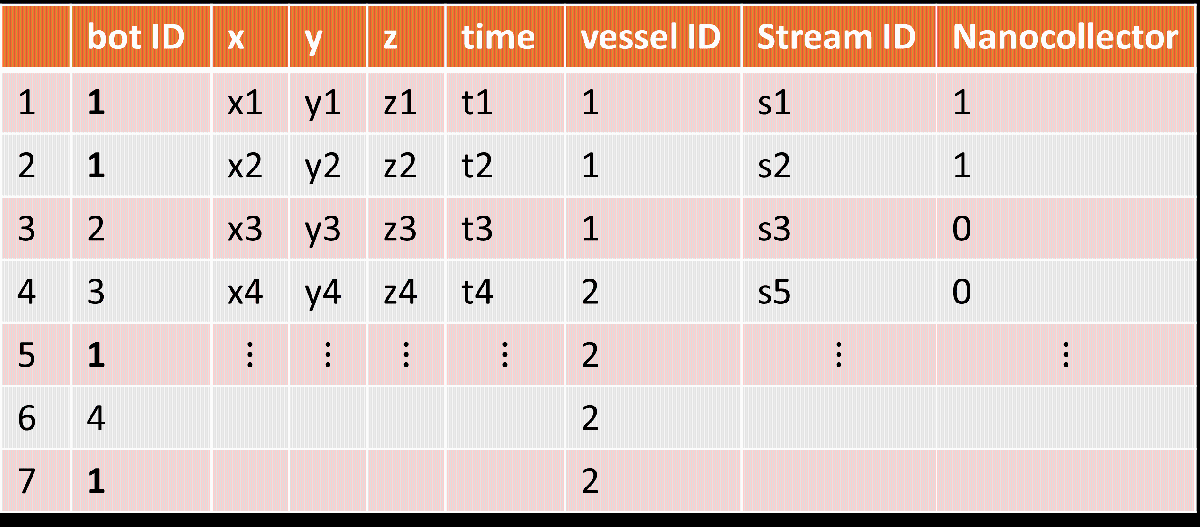

Fig. 3: Table format stored in the CSV file.

**Inputs:**

- data_file_selector: variable to select the file, only in the case there are several ones.

- data_files: stores the name of the file

- botID_column: determines the column in the CSV file for the bot ID.

- time_column: determines the column in the CSV file for the simulation time.

- vesselID_column: specifies the column in the CSV file for the vessel ID.

- nanocollector_column: determines the column in the CSV file to distinguish nanocollectors (1) from nanosensors (0).

- dataAmountPercent: This represents the amount of data to load from the CSV file; it is given in percent. The 100 percent will indicate loading the entire amount of data.

**Outputs:**

- ids_segments: stores the matrix-data according to the CSV file. This matrix stores the all the columns except columns x, y, z in Fig. 3.

dataAmountPercent=100;%percentage of the amount of data to read, in the range (1 100]

data_file_selector=1;%to select the file to read
data_files ={'csvNano_100NC_1000NB_600s.csv', 'csvNano_1000NB_500s.csv'};

opts=detectImportOptions(data_files{data_file_selector});
preview(data_files{data_file_selector},opts) %data file preview

ans = 8×8 table
    Var1    Var2    Var3    Var4    Var5    Var6    Var7    Var8
    ____    ____    ____    ____    ____    ____    ____    ____

     15      0       0       2       0       1       0       1  
     36      0       0       2       0       1       0       1  
     87      0       0       2       0       1       0       1  
     95      0       0       2       0       1       0       1  
    101      0       0       2       0       1       0       0  
    104      0       0       2       0       1       0       0  
    110      0       0       2       0       1       0       0  
    196      0       0       2       0       1       0       0  



botID_column=1;%position in the table for the nanodevice ID
time_column=5;%position in the table for the simulation time
vesselID_column=6;%position in the table for the vessel ID
nanocollector_column=8;%position in the table for the nanocollector distinction

%loading the IDs and segments only
opts.SelectedVariableNames=[botID_column,time_column,vesselID_column,nanocollector_column];
ids_segments=readmatrix(data_files{data_file_selector},opts);
ids_segments=ids_segments(1:round(dataAmountPercent/100*length(ids_segments)),:);

### Reading the path trayectory per nanodevice

**Description:** This block of code reads the path trajectory per nanodevice and stores those in the two-dimensional array path_bot. The path trajectory is the sequence of vessel ID visited for each nanodevice. As depicted in Fig. 3, this code identifies from the matrix "ids_segments" the corresponding entries per nanodevice. These entries are stored in the two-dimensional array "bot_entry_table". For instance, according to the matrix in Fig. 4 entries, 1 for the bot ID is equal to 1, the entries 1,2, 5, and 7 will be the ones for bot ID number 1.

**Inputs:**

- ids_segments: stores the matrix according to the CSV file.

**Outputs:**

- path_bot: Two-dimensional array storing the traveling path per nanodevice as the vessel ID.

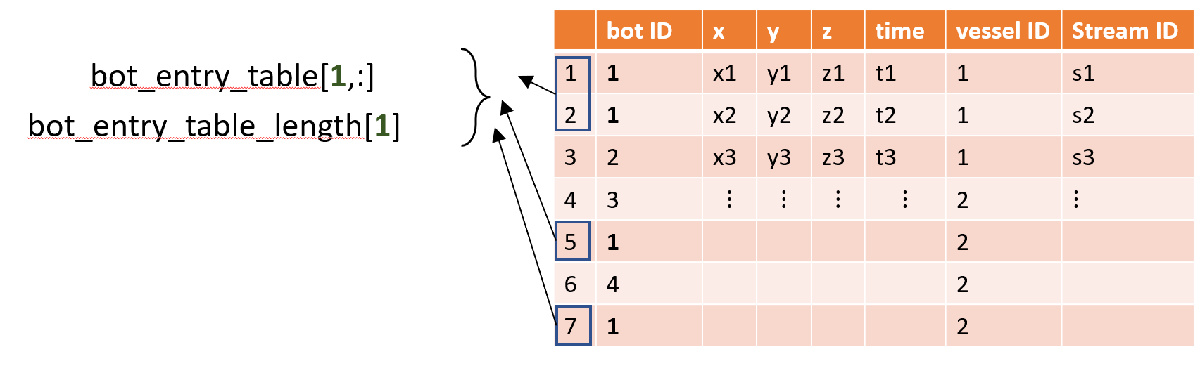

Fig. 4: Illustration to compute the path trayectory per nanodevice from the matrix "ids_segments". 

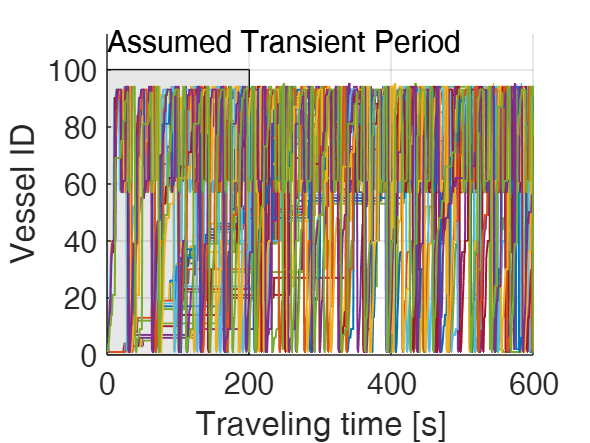

%computing the total of vessels ID
vessels_segments_unique=unique(ids_segments(:,3));
total_vesselsID=length(unique(vessels_segments_unique));

%computing total of nanosensors in the system
ids=ids_segments(:,1);
ids_unique=unique(ids);
total_bots=length(ids_unique);
%computing total of iterations
total_time=length(find(ids_segments(:,1)==ids_unique(1)))-1;%in seconds

%identifying entries in the table per nanodevice according to their IDs
t_initial=1;%initial time to make the readings
bot_entry_table=zeros(total_bots,total_time-t_initial+1);
bot_entry_table_length=zeros(1,total_bots);
for i=1:total_bots
    bot_found=find(ids==i);
    bot_entry_table(i,1:length(bot_found))=bot_found;
    bot_entry_table_length(i)=length(bot_found);
end
total_time=min(bot_entry_table_length); %updating the total of iterations, not all bots have equal total of iterations
bot_entry_table=bot_entry_table(:,t_initial:total_time);% updating the entry table length
clear ids;

%reading all the entries per bot in the table
path_bot=zeros(total_bots,total_time-t_initial+1);
opts.SelectedVariableNames=vesselID_column;%reading the vessels' ID only
data_vesselsID=ids_segments(:,3);

%reading the vessel ID per nanodevice
for i=1:total_bots
    path_bot(i,:)=data_vesselsID(bot_entry_table(i,:));
end

%identifying the nanocollectors IDs
total_time_0=sum(ids_segments(:,2)==0); %total of entries with t=0;
total_nanocollectors=sum(ids_segments(1:total_time_0,4)==1);
nanocollectors_ID=ids_segments(ids_segments(1:total_time_0,4)==1,1);

%plotting the traveling vessel ID
close;
figure;
font=15;
p=patch([0 200 200 0],[0 0 100 100],[0.3010 0.7450 0.9330],"EdgeColor",uint8([17 17 17]),"FaceColor",uint8([17 17 17]));hold on;
set(p,'FaceAlpha',0.1);
for i=1:110
    plot(path_bot(i,:),'LineWidth',1); hold on;
end

text([0,0],[110,110],{'Assumed Transient Period'},'FontSize',font);
grid on;
xlabel('Traveling time [s]');
ylabel('Vessel ID')
axis([0 total_time-t_initial 0 1.2*total_vesselsID]);
% legend('bot 1','bot 2','bot 3');
set(gca,'FontSize',font);


%erasing temporal variables
clear ids_segments data_vesselsID bot_entry_table bot_entry_table_length;

### Computing the traveling time

This section computes the two metrics for each nanodevice, the traveling time and the concentration level of nanosensor along the vessels

#### Traveling time (heart to heart)[ vessel ID vein before left heart = 94 ](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf)

**Description:** This block evaluates the traveling time across the closed circuits. The closed circuits are defined as always starting and ending in the left ventricle in the Heart (see Fig. 1). To evaluate the traveling time, we find the interceptions of the nanodevice's traveling path with the vessel ID equal to 2 (following the corresponding vessel ID in [this link](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf)). As represented in Fig. 5, the interception points are stored in the two-dimensional sequence "t_bot_heart." Then, from this sequence the traveling time is computed as the difference between their consecutive elements as "t_bot_heart[b_ID,t2]-t_bot_heart[b_ID,t1]".

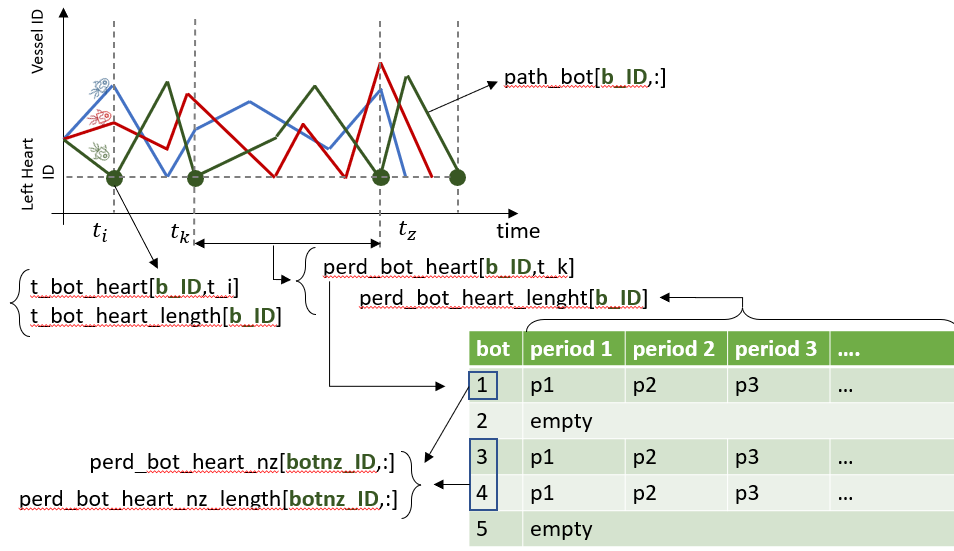

Fig. 5: Illustration to compute the traveling time per nanodevice.

**Inputs:**

- path_bot: Two-dimensional array storing the traveling path per nanodevice as the vessel ID.

**Outputs:**

- t_bot_heart: Two-dimensional array storing the time instants when the nanodevice is at the left Heart. This time instants also correspond to the indexes from "path_both" array, where the vessel ID equals 2.

- t_bot_heart_length: array storing the length of the sequence "t_bot_heart" per nanodevice.

- perd_bot_heart: Two-dimensional array storing the traveling time in a closed circuit.

- perd_bot_heart_length: array storing the length of the sequence "perd_bot_heart" per nanodevice.

heart_vessel_ID=94;%vein before left heart
t_bot_heart_temp=zeros(total_bots,total_time-t_initial+1);%time instants when the nanobot is in the Heart
perd_bot_heart_temp=zeros(total_bots,total_time-t_initial+1);%period of time traveling from the Heart to the Heart
perd_bot_heart_length_temp=zeros(1,total_bots);%total of times passing through the Heart
perd_bot_heart_nz_length=0;%total of bots passing through the Heart at least once
z=1;
for bot=1:total_bots
    t_vector=find(path_bot(bot,:)==heart_vessel_ID);
    period=filter([1 -1],1,t_vector);
    t_bot_heart_temp(bot,1:length(t_vector))=t_vector;
    perd_bot_heart_temp(bot,1:length(period)-1)=period(2:end);
    perd_bot_heart_length_temp(bot)=length(period);
    if(perd_bot_heart_length_temp(bot)~=0)
        perd_bot_heart_nz_length=z;
        z=z+1;
    end
end

%removing periods' intervals equal to 1
t_bot_heart=zeros(total_bots,total_time-t_initial+1);%time instants when the nanobot is in the Heart
t_bot_heart_length=zeros(1,total_bots);%time instants when the nanobot is in the Heart
perd_bot_heart=zeros(total_bots,total_time-t_initial+1);%period of time traveling from the Heart to the Heart
perd_bot_heart_length=zeros(1,total_bots);%total of times passing through the Heart


t_bot_heart(:,1)=t_bot_heart_temp(:,1);
for bot=1:total_bots
    z=1;
    for t=2:(total_time-t_initial+1)
        if(perd_bot_heart_temp(bot,t)>1)
            t_bot_heart(bot,z)=t_bot_heart_temp(bot,t);
            perd_bot_heart(bot,z)=perd_bot_heart_temp(bot,t);
            z=z+1;
        end
    end
    t_bot_heart_length(bot)=z-1;
    perd_bot_heart_length(bot)=z-1;
end

%warning message
if perd_bot_heart_nz_length~=total_bots
    fprintf('A total of %d out of %d nanodevices have still not completed a closed circuit.\nThe simulation time should be longer.\n',total_bots-perd_bot_heart_nz_length,total_bots);
end

A total of 86 out of 1100 nanodevices have still not completed a closed circuit.
The simulation time should be longer.



clear t_bot_heart_temp perd_bot_heart_length_temp

### Computing the concentration level

#### Computing the concentration level per nanosensor per time instant

**Description**: This block computes the total of neighbor nanodevices for each nanodevice. Neighbor nanodevices are defined as those in the same vessel segment. As depicted in Fig. 6, this metric is the interception among traveling paths per nanodevices. The total of intercepted curves per time instant will evaluate the concentration level.

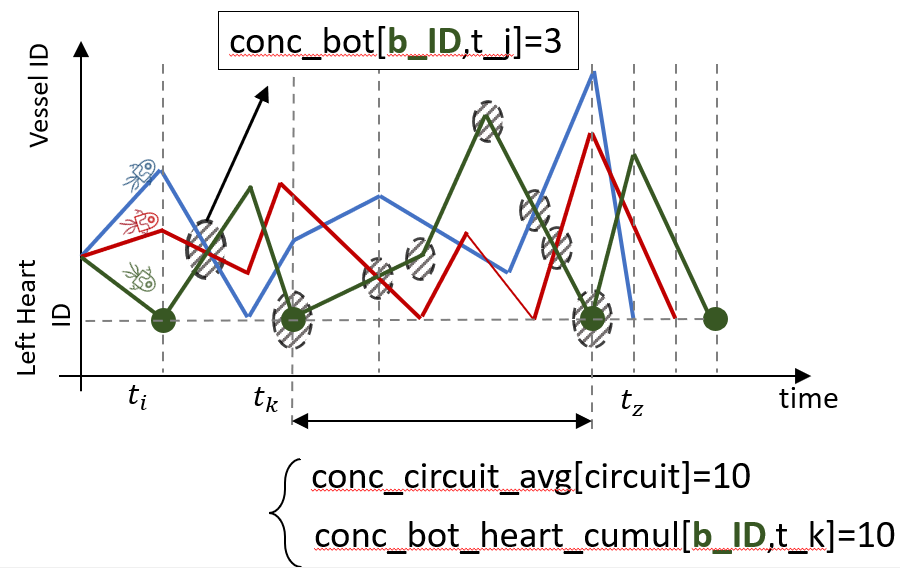

Fig. 6: Illustration to compute the concentration level of nanodevices along vessels.

**Inputs:**

- path_bot: Two-dimensional array storing the traveling path per nanodevice as the vessel ID.

**Outputs:**

- conc_bot: Two-dimensional array storing the concentration level per nanodevice.

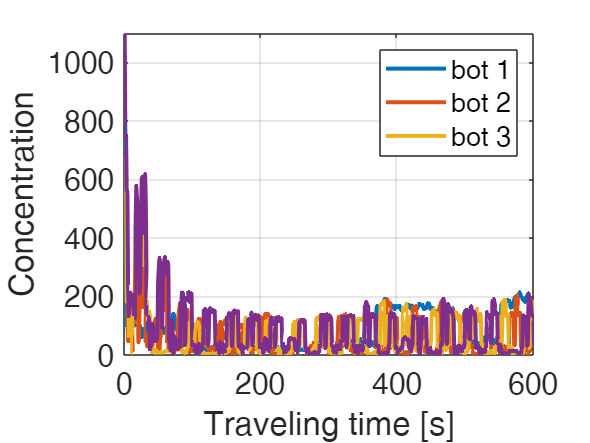

%Computing the total of nanosensors in the same vessel ID per iteration time
conc_bot=zeros(total_bots,total_time-t_initial+1);
for bot=1:total_bots
    for t=1:total_time-t_initial+1
        sample=path_bot(bot,t);
        conc_bot(bot,t)=length(find(path_bot(:,t)==sample));
    end
end

%plotting intermediate results
figure;
for bot=100:103
    plot(conc_bot(bot,:),'LineWidth',2); hold on;
end
grid on;
xlabel('Traveling time [s]');
ylabel('Concentration')
legend('bot 1','bot 2','bot 3');
% axis([0 total_time 0 total_vesselsID]);
set(gca,'FontSize',font);

#### Computing the cumulative and average concentration level reported at the Heart

**Description:** This block computes the cumulative and average concentration level along the traveling time in the closed circuit. The code accumulates and average the total of neighbor nanodevices found for the traveling nanodevice.

**Inputs:**

- conc_bot: Two-dimensional array storing the concentration level per nanodevice.

**Outputs:**

- conc_bot_heart_cumul: Two-dimensional array storing the total of neighbor nanodevices along the ones nanodevice path (in a closed circuit).

- conc_bot_heart_avg: Two-dimensional array storing the average of neighbor nanodevices along the ones nanodevice path (in a closed circuit).

conc_bot_heart_cumul=zeros(perd_bot_heart_nz_length,total_time-t_initial+1);
conc_bot_heart_avg=zeros(perd_bot_heart_nz_length,total_time-t_initial+1);
for bot=1:total_bots
    t_bot_heart_vector=t_bot_heart(bot,:);
    %accumulating
    cumul=0;
    for j=1:perd_bot_heart_length(bot)-1
        t1=t_bot_heart_vector(j);
        t2=t_bot_heart_vector(j+1);
        conc_bot_heart_cumul(bot,j)=sum(conc_bot(bot,t1:t2));
        conc_bot_heart_avg(bot,j)=mean(conc_bot(bot,t1:t2));
    end
    
end

#### Identifying the circuit per bot along their traveling circuit

**Description:** This block evaluates the traveled circuit per nanodevice along the HCS. The circuit is found looking for the tissues ID on each closed path. On each closed path, the nanodevice will visit only once a given tissue according to the blood flow in the HCS (see Fig. 1). Closed paths are identified by looking at the "path_bot" array between the left heart ID, where the circuit closes. The index to look at is given by the array "t_bot_heart." The tissues (capillary system) are labeled according to the corresponding vessels IDs in BVS (see [this link](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf)).

**Inputs:**

- circuits_tissues: array storing the vessels IDs corresponding to each different tissue (capillary system) in the body. Tissues are labeled according to BVS documentation (see [this link](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf)).

- t_bot_heart: Two-dimensional array storing the time instants when the nanodevice is at the left Heart. This time instants also correspond to the indexes from "path_both" array, where the vessel ID equals 94.

- t_bot_heart_length: array storing the length of the sequence "t_bot_heart" per nanodevice.

**Outputs:**

- circuit_per_bot: Two-dimensional array storing the tissue (capillary system) per nanodevice. The tissue is labeled according to BVS documentation (see [this link](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf)).

%labeling the circuits in HCS
circuits_tissues=[%Upper Body
          9 ...%Head
          17 ...%Left Shoulder 
          11 ...%Right Shoulder          
          23 ...%Left Upper Arm
          15 ...%Right Upper Arm          
          29 ...%Left Elbow
          21 ...%Right Elbow
          33 ...%Left Hand
          27 ...%Right Hand           
          ...%Center Body
          24 ...%Chest and back
          30 ...%Spleen
          40 ...%Kidneys
          36 ...%Liver
          39 ...%Intestine
          ...%Lower Body
          49 ...%Left Hip
          52 ...%Right Hip
          47 ...%Left Pelvis and Genitales
          51 ...%Right Pelvis and Genitales
          54 ...%Left Knee
          56 ...%Right Knee
          59 ...%Left Foot
          60 ...%Right Foot
          ];

circuit_per_bot=zeros(total_bots,total_time-t_initial+1);

for bot=1:total_bots
    %iterations over length -1 so that only full cycles are counted 
    for t=1:t_bot_heart_length(bot)-1 
        t_heart_1=t_bot_heart(bot,t);
        t_heart_2=t_heart_1+perd_bot_heart(bot,t);
        for c=1:length(circuits_tissues)
            c_period=find(path_bot(bot,t_heart_1:t_heart_2)==circuits_tissues(c));
            if (~isempty(c_period))
                circuit_per_bot(bot,t)=circuits_tissues(c);
                break;
            end
        end
    end
end

#### Computing delay, cumulative concentration, average concentration, avg concentration curves per circuit

**Description:** This block computes delay, cumulative, and average concentration levels per circuit as reported by the nanodevices. These metrics are evaluated using the previous arrays for the cumulative and average concentration values reported at the heart. For instance, the array "conc_bot_heart_cumul" is indexed only for a given circuit in order to accumulate only those values belonging to the specific circuit. This indexes are found looking at the array "circuit_per_bot" for the given circuit index, the corresponding index matches the time instant when the nanosensor visits the given tissue.

**Inputs:**

- circuit_per_bot: Two-dimensional array storing the tissue (capillary system) per nanodevice. The tissue is labeled according to BVS documentation (see [this link](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf)).

- circuits_tissues: array storing the vessels IDs corresponding to each different tissue (capillary system) in the body. Tissues are labeled according to BVS documentation (see [this link](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf)).

- perd_bot_heart: Two-dimensional array storing the traveling time in a closed circuit. 

**Outputs:**

- conc_cumul_circuit: Cell of arrays storing the cumulative concentration level reported at the heart on each different circuit (total of 22 according to the different tissues).

- conc_avg_circuit: Cell of arrays storing the average concentration level reported at the heart on each different circuit (total of 22 according to the different tissues).

- delay_circuit: Cell of arrays storing the traveling times reported at the heart on each different circuit (total of 22 according to the different tissues).

delay_circuit=cell(1,length(circuits_tissues));
conc_cumul_circuit=cell(1,length(circuits_tissues));
conc_avg_circuit=cell(1,length(circuits_tissues));
path_circuit_avg=cell(1,length(circuits_tissues));
path_delay=zeros(1,total_time-t_initial+1);
path_conc_cumul_temp=zeros(1,total_time-t_initial+1);
path_conc_avg_temp=zeros(1,total_time-t_initial+1);

for c=1:length(circuits_tissues)
    first_entry=1;
    z=1;
    for bot=1:total_bots
        index_circ_temp=find(circuit_per_bot(bot,:)==circuits_tissues(c));%returns the indexes for the given circuit
        for j=1:length(index_circ_temp)
            t_1=t_bot_heart(bot,index_circ_temp(j));
            t_2=t_1+perd_bot_heart(bot,index_circ_temp(j));
            path_conc_cumul_temp(z)=conc_bot_heart_cumul(bot,index_circ_temp(j));
            path_conc_avg_temp(z)=conc_bot_heart_avg(bot,index_circ_temp(j));
            path_delay(z)=t_2-t_1+1;
            z=z+1;           
        end
    end
    delay_circuit{c}=path_delay(1:z-1);
    conc_cumul_circuit{c}=path_conc_cumul_temp(1:z-1);
    conc_avg_circuit{c}=path_conc_avg_temp(1:z-1);
end

clear index_circ_temp path_conc_cumul_temp path_conc_avg_temp;

#### Computing cross-correlation per circuit

**Description:** This code computes the cross-correlation between the sequence reported by each nanodevice and the average on the given circuit. All the resulting cross-correlation values are stored in one arry. The cross-correlation is evaluated using the "xcorr" function in matlab. The indexing for the concentration level per nanodevice is implemented using the sequence "index_circ_temp".

**Inputs:**

- circuit_per_bot: Two-dimensional array storing the tissue (capillary system) per nanodevice. The tissue is labeled according to BVS documentation (see [this link](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf)).

- circuits_tissues: One-dimensional array storing the vessels IDs corresponding to each different tissue (capillary system) in the body. Tissues are labeled according to BVS documentation (see [this link](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf)).

**Outputs:**

- conc_cross_circuit: One-dimensional cell array storing the cross-correlation per circuit. 


conc_cross_circuit=cell(1,length(circuits_tissues));
path_cross_corr_temp=zeros(1,total_time-t_initial+1);

flag=0;%used as an indicator that at least once the nanodevice traveled through at least one circuit
for c=1:length(circuits_tissues)
    z=1;
    for bot=1:total_bots
        index_circ_temp=find(circuit_per_bot(bot,:)==circuits_tissues(c));
        if(~isempty(index_circ_temp))
            for j=1:length(index_circ_temp)
                t_1=t_bot_heart(bot,index_circ_temp(j));
                t_2=t_1+perd_bot_heart(bot,index_circ_temp(j));
                cross_temp=xcorr(conc_bot(bot,t_1:t_2),conc_avg_circuit{c});
                %computing cross-corr when evaluating it at its maximum
                path_cross_corr_temp(z)=max(cross_temp);
                z=z+1;
                flag=1;
            end
        end        
    end
    if(flag)
        conc_cross_circuit{c}=path_cross_corr_temp(1:z-1);
        flag=0;
    end        
end

clear path_cross_corr_temp index_circ_temp

## Saving Data for the ML model

**Description:** This code saves the traveling time and cross-concentration level per nanosensor along the traveling circuit. These data are stored in the file "BVS_training_data.mat", where the delay and cross-concentration per circuit (tissue) are stored as separate arrays irrespective of the nanodevice. In the case of symmetrical tissues in the body like left and right shoulders, elbows, etc., the data is concatenated into a single array. In addition, this code also saves data in "BVS_data.mat" related to traveling times and concentration levels for each nanodevice. 

These stored data models can be used for applications that need to identify the traveling circuit for nanodevices. For instance, as represented in Fig. 7, nanodevices traveling through the heart can send to the external Gateway its data concerning the traveling time and the concentration level (later evaluated as cross-concentration). Then, a classifier or an ML model may use this data to predict its traveling circuit.

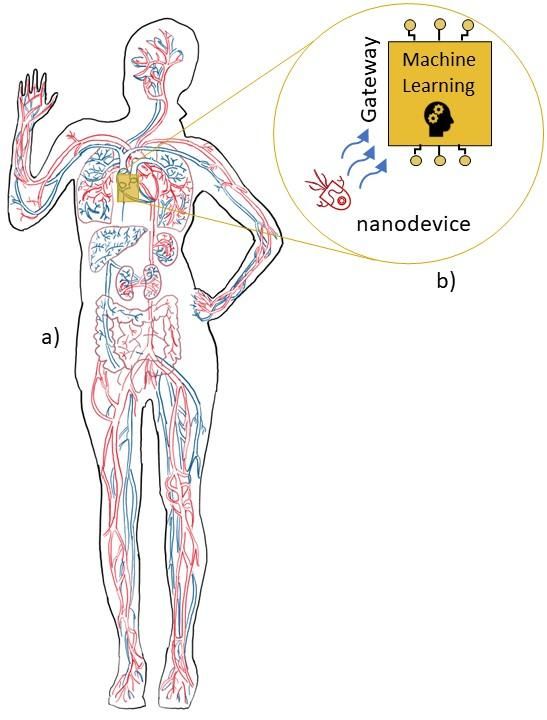

Fig. 7: System model for the nanosensors traveling through the human circulatory system in a) 

and reporting its data to the external gateway  in b).

**Inputs: **

- delay_circuit: Cell of arrays storing the traveling times reported at the heart on each different circuit (total 22 according to the different tissues).

- conc_cross_circuit: one-dimensional array storing the cross-concentration of nanodevices along the circuits.

- vessels_ID: one-dimensional array storing the labels for the vessel IDs used to identify each different vessel segment. According to BVS each different vessel segment is given as an integer value (see [this link](https://github.com/RegineWendt/blood-voyager-s/blob/master/Images/table1.pdf)).

**Outputs:**

- BVS_training_data.mat: Matlab file storing the delays and cross-concentration levels along the different circuits.

- BVS_data.mat: Matlab file storing the traveling times and concentration level for each nanodevice.

%labeling the tissues versus circuits
%Upper Body
vessels_ID=zeros(1,total_vesselsID);
vessels_ID(9)=1;%Head
vessels_ID(17)=2;%Left Shoulder
vessels_ID(11)=3;%Right Shoulder
vessels_ID(23)=4;%Left Hand
vessels_ID(15)=5;%Right Hand
vessels_ID(29)=6;%Left Elbow
vessels_ID(21)=7;%Right Elbow
vessels_ID(33)=8;%Left Hand
vessels_ID(27)=9;%Right Hand
%Center Body
vessels_ID(24)=10;%Chest and Back
vessels_ID(30)=11;%Spleen
vessels_ID(40)=12;%Kidneys
vessels_ID(36)=13;%Liver
vessels_ID(39)=14;%Intestine
%Lower Body
vessels_ID(49)=15;%Left Hip
vessels_ID(52)=16;%Right Hip
vessels_ID(47)=17;%Left Pelvis and Genitales
vessels_ID(51)=18;%Right Pelvis and Genitales
vessels_ID(54)=19;%Left Knee
vessels_ID(56)=20;%Right Knee
vessels_ID(59)=21;%Left Foot
vessels_ID(60)=22;%Right Foot
c1=9;%Head
delay_Head=delay_circuit{vessels_ID(c1)};
conc_cross_Head=conc_cross_circuit{vessels_ID(c1)};
conc_avg_Head=conc_avg_circuit{vessels_ID(c1)};
%Upper Body
c1=11;%Right Shoulder
c2=17;%Left Shoulder
delay_Shoulders=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Shoulders=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
conc_avg_Shoulders=horzcat(conc_avg_circuit{vessels_ID(c1)},conc_avg_circuit{vessels_ID(c2)});
c1=15;%Right Upper Arm
c2=23;%Left Upper Arm
delay_UpperArms=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_UpperArms=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
conc_avg_UpperArms=horzcat(conc_avg_circuit{vessels_ID(c1)},conc_avg_circuit{vessels_ID(c2)});
c1=21;%Right Elbow
c2=29;%Left Elbow
delay_Elbows=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Elbows=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
conc_avg_Elbows=horzcat(conc_avg_circuit{vessels_ID(c1)},conc_avg_circuit{vessels_ID(c2)});
c1=27;%Right Hand
c2=33;%Right Hand
delay_Hands=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Hands=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
conc_avg_Hands=horzcat(conc_avg_circuit{vessels_ID(c1)},conc_avg_circuit{vessels_ID(c2)});

%Center Body
c1=24; %Chest and back
delay_Thorax=delay_circuit{vessels_ID(c1)};
conc_cross_Thorax=conc_cross_circuit{vessels_ID(c1)};
conc_avg_Thorax=conc_avg_circuit{vessels_ID(c1)};
c1=30; %Spleen
delay_Spleen=delay_circuit{vessels_ID(c1)};
conc_cross_Spleen=conc_cross_circuit{vessels_ID(c1)};
conc_avg_Spleen=conc_avg_circuit{vessels_ID(c1)};
c1=40;%Kidneys
delay_Kidneys=delay_circuit{vessels_ID(c1)};
conc_cross_Kidneys=conc_cross_circuit{vessels_ID(c1)};
conc_avg_Kidneys=conc_avg_circuit{vessels_ID(c1)};
c1=36;%Liver
delay_Liver=delay_circuit{vessels_ID(c1)};
conc_cross_Liver=conc_cross_circuit{vessels_ID(c1)};
conc_avg_Liver=conc_avg_circuit{vessels_ID(c1)};
c1=39;%Intestine
delay_Intestine=delay_circuit{vessels_ID(c1)};
conc_cross_Intestine=conc_cross_circuit{vessels_ID(c1)};
conc_avg_Intestine=conc_avg_circuit{vessels_ID(c1)};
c1=47;%Pelvis
c2=51;
delay_Pelvis=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Pelvis=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
conc_avg_Pelvis=horzcat(conc_avg_circuit{vessels_ID(c1)},conc_avg_circuit{vessels_ID(c2)});

%Lower Body
c1=49;%Left Hip
c2=52;%Right Hip
delay_Hips=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Hips=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
conc_avg_Hips=horzcat(conc_avg_circuit{vessels_ID(c1)},conc_avg_circuit{vessels_ID(c2)});
c1=54;%Left Knee
c2=56;%Left Knee
delay_Knees=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Knees=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
conc_avg_Knees=horzcat(conc_avg_circuit{vessels_ID(c1)},conc_avg_circuit{vessels_ID(c2)});
c1=59;%Left Feet
c2=60;%Right Feet
delay_Feet=horzcat(delay_circuit{vessels_ID(c1)},delay_circuit{vessels_ID(c2)});
conc_cross_Feet=horzcat(conc_cross_circuit{vessels_ID(c1)},conc_cross_circuit{vessels_ID(c2)});
conc_avg_Feet=horzcat(conc_avg_circuit{vessels_ID(c1)},conc_avg_circuit{vessels_ID(c2)});

save BVS_training_data.mat delay_Head conc_cross_Head conc_avg_Head delay_Shoulders conc_cross_Shoulders conc_avg_Shoulders delay_UpperArms conc_cross_UpperArms conc_avg_UpperArms ...%Upper Body
     delay_Elbows conc_cross_Elbows conc_avg_Elbows delay_Hands conc_cross_Hands conc_avg_Hands delay_Thorax conc_cross_Thorax conc_avg_Thorax delay_Spleen conc_cross_Spleen conc_avg_Spleen ... %Center Body
     delay_Kidneys conc_cross_Kidneys conc_avg_Kidneys delay_Liver conc_cross_Liver conc_avg_Liver delay_Intestine conc_cross_Intestine conc_avg_Intestine delay_Pelvis conc_cross_Pelvis conc_avg_Pelvis ...%Center Body
     delay_Hips conc_cross_Hips conc_avg_Hips delay_Knees conc_cross_Knees conc_avg_Knees delay_Feet conc_cross_Feet conc_avg_Feet; %Lower Body


save BVS_data.mat path_bot t_bot_heart t_bot_heart_length perd_bot_heart perd_bot_heart_length perd_bot_heart_nz_length ...
     path_circuit_avg conc_bot_heart_cumul

## Plots: 1D

### Plotting the traveling time per Tissue

figure;
%Head
subplot 411;
c=9;%Head
h=histogram(delay_circuit{vessels_ID(c)})

h =   Histogram with properties:

             Data: [30 32 32 32 30 31 33 32 32 29 30 31 31 31 31 33 33 32 30 30 31 32 33 31 31 31 31 30 31 32 31 32 33 31 33 33 33 32 33 33 33 31 30 30 31 32 32 32 32 32 32 33 32 32 33 32 33 32 32 32 31 32 33 32 31 29 31 32 32 31 29 31 33 32 32 32 32 … ]
           Values: [33 291 658 760 482 5]
          NumBins: 6
         BinEdges: [28.5000 29.5000 30.5000 31.5000 32.5000 33.5000 34.5000]
         BinWidth: 1
        BinLimits: [28.5000 34.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


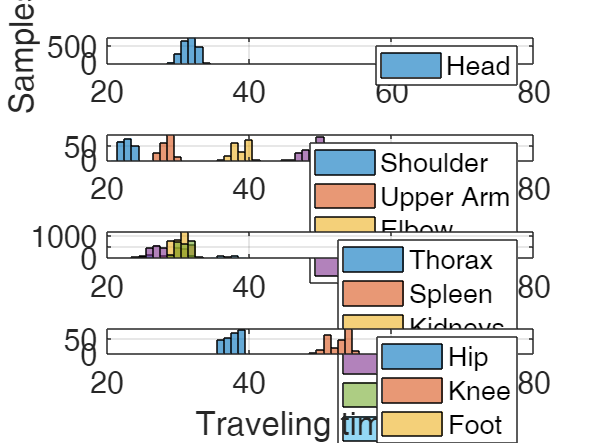

grid on
ylabel('Samples');
axis([20 80 0 max(h.Values)]);
legend('Head');
set(gca,'FontSize',font);

subplot 412;
%Upper Body
c=11;%Right Shoulder
h_1=histogram(delay_circuit{vessels_ID(c)}); hold on;
c=15;%Right Upper Arm 
h_2=histogram(delay_circuit{vessels_ID(c)});
c=21;%Right Elbow
h_3=histogram(delay_circuit{vessels_ID(c)});
c=27;%Right Hand 
h_4=histogram(delay_circuit{vessels_ID(c)});
grid on
axis([20 80 0 max([h_1.Values h_2.Values h_3.Values h_4.Values])]);
legend('Shoulder','Upper Arm','Elbow','Hand');
set(gca,'FontSize',font);

subplot 413;
%Center Body
c=24; %Chest and back
h_1=histogram(delay_circuit{vessels_ID(c)}); hold on;
c=30; %Spleen
h_2=histogram(delay_circuit{vessels_ID(c)});
c=40;%Kidneys
h_3=histogram(delay_circuit{vessels_ID(c)});
c=36;%Liver
h_4=histogram(delay_circuit{vessels_ID(c)});
c=39;%Intestine
h_5=histogram(delay_circuit{vessels_ID(c)});
c=47;%Pelvis
h_6=histogram(delay_circuit{vessels_ID(c)});
grid on
axis([20 80 0 max([h_1.Values h_2.Values h_3.Values h_4.Values h_5.Values h_6.Values])]);
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
set(gca,'FontSize',font);

subplot 414;
%Lower Body
c=49;%Left Hip
h_1=histogram(delay_circuit{vessels_ID(c)}); hold on;
c=54;%Left Knee
h_2=histogram(delay_circuit{vessels_ID(c)});
c=59;%Left Foot
h_3=histogram(delay_circuit{vessels_ID(c)});
grid on
axis([20 80 0 max([h_1.Values h_2.Values h_3.Values])]);
xlabel('Traveling time [s]');
set(gca,'FontSize',font);
legend('Hip','Knee','Foot');


%uncomment the  following two lines for saving the plot, these lines require R2020a or later
% f=gcf;
% exportgraphics(f,'delay_circuit_histogram.png','Resolution',300);

### Plotting cumul concentration histogram per Body Region

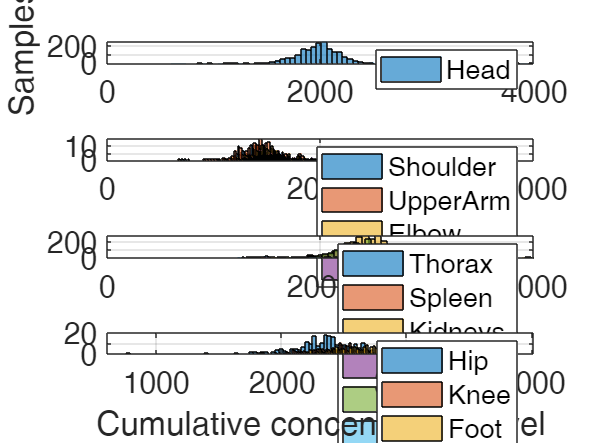

figure;
bins=100;

subplot 411
c=9;%Head
h=histogram(conc_cumul_circuit{vessels_ID(c)},bins); hold on;
legend('Head');
set(gca,'FontSize',font);
grid on;
axis([0 4000 0 max(h.Values)]);
ylabel('Samples');

subplot 412
%Upper Body
c=11;%Right Shoulder
h_1=histogram(conc_cumul_circuit{vessels_ID(c)},bins); hold on;
c=15;%Right Upper Arm 
h_2=histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=21;%Right Elbow
h_3=histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=27;%Right Hand 
h_4=histogram(conc_cumul_circuit{vessels_ID(c)},bins);
legend('Shoulder','UpperArm','Elbow','Hand');
set(gca,'FontSize',font);
grid on;
axis([0 4000 0 max([h_1.Values h_2.Values h_3.Values h_4.Values])]);


%Center Body
subplot 413
c=24; %Chest and back
h_1=histogram(conc_cumul_circuit{vessels_ID(c)},bins); hold on;
c=30; %Spleen
h_2=histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=40;%Kidneys
h_3=histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=36;%Liver
h_4=histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=39;%Intestine
h_5=histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=47;%Pelvis
h_6=histogram(conc_cumul_circuit{vessels_ID(c)},bins);
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
set(gca,'FontSize',font);
grid on;
axis([0 4000 0 max([h_1.Values h_2.Values h_3.Values h_4.Values h_5.Values h_6.Values])]);

subplot 414
%Lower Body
c=49;%Left Hip
histogram(conc_cumul_circuit{vessels_ID(c)},bins);hold on;
c=54;%Left Knee
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
c=59;%Left Foot
histogram(conc_cumul_circuit{vessels_ID(c)},bins);
legend('Hip','Knee','Foot');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);
xlabel('Cumulative concentration level');

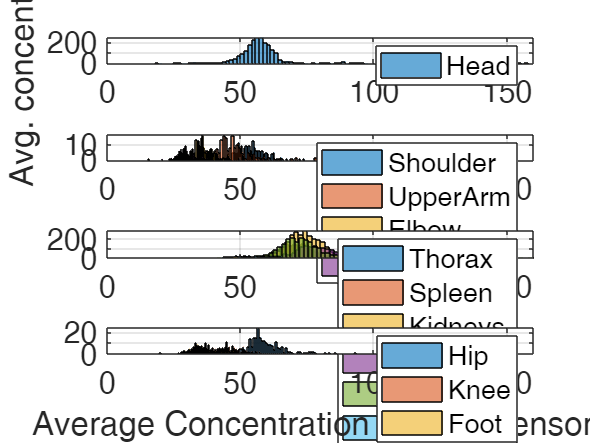


%uncomment the  following two lines for saving the plot, these lines require R2020a or later
% f=gcf;
% exportgraphics(f,'delay_circuit_histogram.png','Resolution',300);

### Plotting avg concentration curves per Body Region

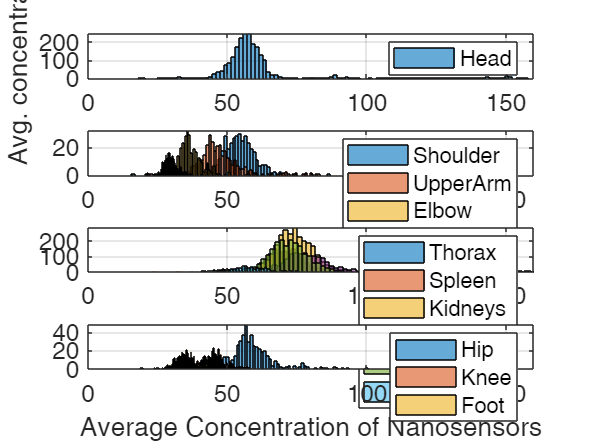

figure;
bins=100;

%Head
subplot 411
h=histogram(conc_avg_Head,bins); hold on;
ylabel('Avg. concentration');
legend('Head');
set(gca,'FontSize',font);
grid on;
axis([0 160 0 max([h.Values])]);

%Upper Body
subplot 412
h_1=histogram(conc_avg_Shoulders,bins);hold on;
h_2=histogram(conc_avg_UpperArms,bins);
h_3=histogram(conc_avg_Elbows,bins);
h_4=histogram(conc_avg_Hands,bins);
legend('Shoulder','UpperArm','Elbow','Hand');
set(gca,'FontSize',font);
grid on;
axis([0 160 0 max([h_1.Values h_2.Values h_3.Values h_4.Values])]);


%Center Body
subplot 413
h_1=histogram(conc_avg_Thorax,bins); hold on;
h_2=histogram(conc_avg_Spleen,bins);
h_3=histogram(conc_avg_Kidneys,bins);
h_4=histogram(conc_avg_Liver,bins);
h_5=histogram(conc_avg_Intestine,bins);
h_6=histogram(conc_avg_Pelvis,bins);
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
set(gca,'FontSize',font);
grid on;
axis([0 160 0 max([h_1.Values h_2.Values h_3.Values h_4.Values h_5.Values h_6.Values])]);

%Lower Body
subplot 414
h_1=histogram(conc_avg_Hips,bins);hold on;
h_2=histogram(conc_avg_Knees,bins);
h_3=histogram(conc_avg_Feet,bins);
legend('Hip','Knee','Foot');
set(gca,'FontSize',font);
grid on;
axis([0 160 0 max([h_1.Values h_2.Values h_3.Values])]);
xlabel('Average Concentration of Nanosensors');


%uncomment the  following two lines for saving the plot, these lines require R2020a or later
% f=gcf;
% exportgraphics(f,'delay_circuit_histogram.png','Resolution',300);

### Plotting cross-correlation per circuit

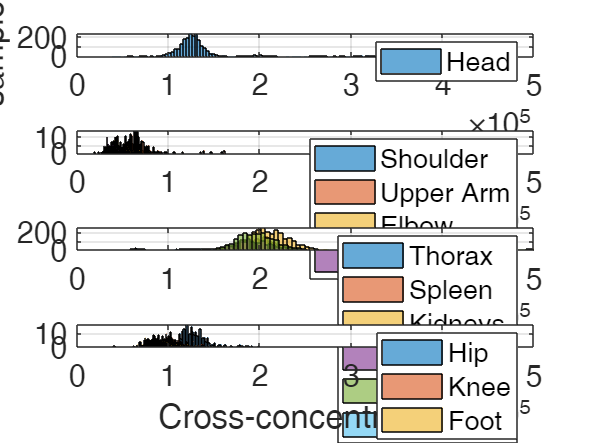

figure;
bins=100;
%Head
subplot 411;
c=9;%Head
h=histogram(conc_cross_circuit{vessels_ID(c)},bins);
grid on
ylabel('samples');
axis([0 5*10^5 0 max(h.Values)]);
legend('Head');
set(gca,'FontSize',font);
clear h;

subplot 412;
%Upper Body
c=11;%Right Shoulder
h_1=histogram(conc_cross_circuit{vessels_ID(c)},bins); hold on;
c=15;%Right Upper Arm 
h_2=histogram(conc_cross_circuit{vessels_ID(c)},bins);
c=21;%Right Elbow
h_3=histogram(conc_cross_circuit{vessels_ID(c)},bins);
c=27;%Right Hand 
h_4=histogram(conc_cross_circuit{vessels_ID(c)},bins);
grid on
axis([0 5*10^5 0 max([h_1.Values h_2.Values h_3.Values h_4.Values])]);
legend('Shoulder','Upper Arm','Elbow','Hand');
set(gca,'FontSize',font);

subplot 413;
%Center Body
c=24; %Chest and back
h_1=histogram(conc_cross_circuit{vessels_ID(c)},bins); hold on;
c=30; %Spleen
h_2=histogram(conc_cross_circuit{vessels_ID(c)},bins);
c=40;%Kidneys
h_3=histogram(conc_cross_circuit{vessels_ID(c)},bins);
c=36;%Liver
h_4=histogram(conc_cross_circuit{vessels_ID(c)},bins);
c=39;%Intestine
h_5=histogram(conc_cross_circuit{vessels_ID(c)},bins);
c=47;%Pelvis
h_6=histogram(conc_cross_circuit{vessels_ID(c)},bins);
grid on
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
axis([0 5*10^5 0 max([h_1.Values h_2.Values h_3.Values h_4.Values h_5.Values h_6.Values])]);
set(gca,'FontSize',font);

subplot 414;
%Lower Body
c=49;%Left Hip
h_1=histogram(conc_cross_circuit{vessels_ID(c)},bins); hold on;
c=54;%Left Knee
h_2=histogram(conc_cross_circuit{vessels_ID(c)},bins);
c=59;%Left Foot
h_3=histogram(conc_cross_circuit{vessels_ID(c)},bins);
grid on
axis([0 5*10^5 0 max([h_1.Values h_2.Values h_3.Values])]);
legend('Hip','Knee','Foot');
xlabel('Cross-concentration');
set(gca,'FontSize',font);


%uncomment the  following two lines for saving the plot, these lines require R2020a or later
% f=gcf;
% exportgraphics(f,'delay_circuit_histogram.png','Resolution',300);

## 2D Plots: Traveling time vs cross-concentration

### Plotting the delay vs cross-concentration

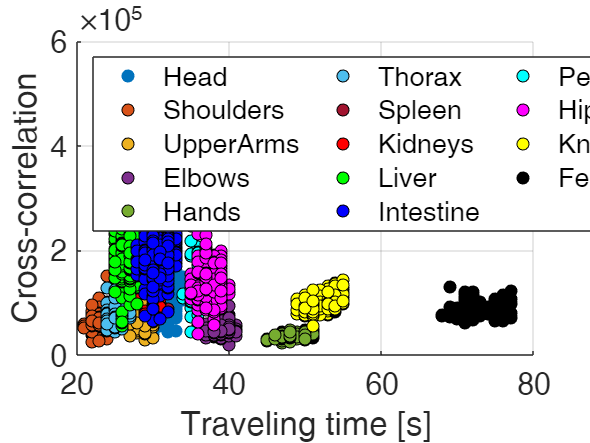

total_samples_plot=800;%total samples per circuit
figure;
color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F','#FF0000','#00FF00','#0000FF','#00FFFF','#FF00FF','#FFFF00','#000000','#FFFFFF'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html

p9=scatter(delay_Head,conc_cross_Head,'MarkerFaceColor',color{1},'MarkerEdgeColor',color{1}); hold on;
%Upper Body
%Right Shoulder
p11=scatter(delay_Shoulders,conc_cross_Shoulders,'MarkerFaceColor',color{2},'MarkerEdgeColor','#000000');
%Right Upper Arm
p15=scatter(delay_UpperArms,conc_cross_UpperArms,'MarkerFaceColor',color{3},'MarkerEdgeColor','#000000');
%Right Elbow
p21=scatter(delay_Elbows,conc_cross_Elbows,'MarkerFaceColor',color{4},'MarkerEdgeColor','#000000');
%Right Hand
p27=scatter(delay_Hands,conc_cross_Hands,'MarkerFaceColor',color{5},'MarkerEdgeColor','#000000');


%Center Body
%Chest and back
p24=scatter(delay_Thorax,conc_cross_Thorax,'MarkerFaceColor',color{6},'MarkerEdgeColor','#000000');
%Spleen
p30=scatter(delay_Spleen,conc_cross_Spleen,'MarkerFaceColor',color{7},'MarkerEdgeColor','#000000');
%Kidneys
p40=scatter(delay_Kidneys,conc_cross_Kidneys,'MarkerFaceColor',color{8},'MarkerEdgeColor','#000000');
%Liver
p36=scatter(delay_Liver,conc_cross_Liver,'MarkerFaceColor',color{9},'MarkerEdgeColor','#000000');
%Intestine
p39=scatter(delay_Intestine,conc_cross_Intestine,'MarkerFaceColor',color{10},'MarkerEdgeColor','#000000');
%Pelvis
p47=scatter(delay_Pelvis,conc_cross_Pelvis,'MarkerFaceColor',color{11},'MarkerEdgeColor','#000000');

%Lower Body
%Left Hip
p49=scatter(delay_Hips,conc_cross_Hips,'MarkerFaceColor',color{12},'MarkerEdgeColor','#000000');hold on;
%Left Knee
p54=scatter(delay_Knees,conc_cross_Knees,'MarkerFaceColor',color{13},'MarkerEdgeColor','#000000');
%Left Foot
p59=scatter(delay_Feet,conc_cross_Feet,'MarkerFaceColor',color{14},'MarkerEdgeColor','#000000');

grid on;
legend([p9 p11 p15 p21 p27 p24 p30 p40 p36 p39 p47 p49 p54 p59],{'Head','Shoulders','UpperArms','Elbows','Hands','Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis','Hips','Knees','Feet'},'Location','northwest','NumColumns',3);
ylabel('Cross-correlation')
set(gca,'FontSize',font);
grid on;
xlabel('Traveling time [s]');


%uncomment the  following two lines for saving the plot, these lines require R2020a or later
% f=gcf;
% exportgraphics(f,'delay_circuit_histogram.png','Resolution',300);

### Plotting the delay vs cross-correlation per Body Region

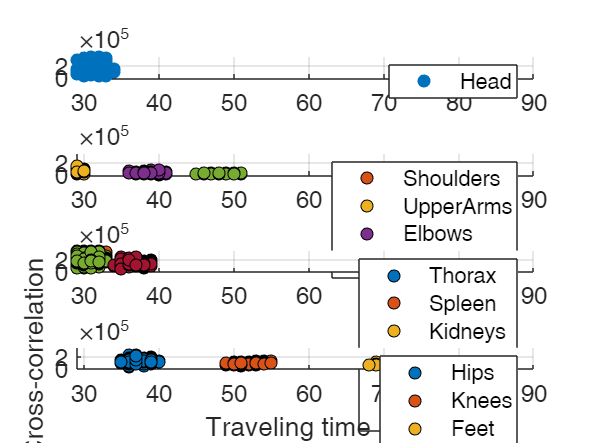

close all;
color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F','#FF0000','#00FF00','#0000FF','#00FFFF','#FF00FF','#FFFF00','#000000','#FFFFFF'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html

font=12;
figure;
subplot 411
p9=scatter(delay_Head,conc_cross_Head,'MarkerFaceColor',color{1},'MarkerEdgeColor',color{1}); hold on;
grid on;
legend(p9,{'Head'});
set(gca,'FontSize',font);
axis([29 90 0 3.5e5]);

subplot 412
%Upper Body
%Right Shoulder
p11=scatter(delay_Shoulders,conc_cross_Shoulders,'MarkerFaceColor',color{2},'MarkerEdgeColor','#000000'); hold on;
%Right Upper Arm
p15=scatter(delay_UpperArms,conc_cross_UpperArms,'MarkerFaceColor',color{3},'MarkerEdgeColor','#000000');
%Right Elbow
p21=scatter(delay_Elbows,conc_cross_Elbows,'MarkerFaceColor',color{4},'MarkerEdgeColor','#000000');
%Right Hand
p27=scatter(delay_Hands,conc_cross_Hands,'MarkerFaceColor',color{5},'MarkerEdgeColor','#000000');
grid on;
legend([p11 p15 p21 p27],{'Shoulders','UpperArms','Elbows','Hands'});
set(gca,'FontSize',font);
axis([29 90 0 3.5e5]);

%Center Body
subplot 413
%Chest and back
p24=scatter(delay_Thorax,conc_cross_Thorax,'MarkerFaceColor',color{1},'MarkerEdgeColor','#000000'); hold on;
%Spleen
p30=scatter(delay_Spleen,conc_cross_Spleen,'MarkerFaceColor',color{2},'MarkerEdgeColor','#000000');
%Kidneys
p40=scatter(delay_Kidneys,conc_cross_Kidneys,'MarkerFaceColor',color{3},'MarkerEdgeColor','#000000');
%Liver
p36=scatter(delay_Liver,conc_cross_Liver,'MarkerFaceColor',color{4},'MarkerEdgeColor','#000000');
%Intestine
p39=scatter(delay_Intestine,conc_cross_Intestine,'MarkerFaceColor',color{5},'MarkerEdgeColor','#000000');
%Pelvis
p47=scatter(delay_Pelvis,conc_cross_Pelvis,'MarkerFaceColor',color{7},'MarkerEdgeColor','#000000');
legend([p24 p30 p40 p36 p39 p47],{'Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis'});
grid on;
set(gca,'FontSize',font);
axis([29 90 0 3.5e5]);

%Lower Body
subplot 414
%Left Hip
p49=scatter(delay_Hips,conc_cross_Hips,'MarkerFaceColor',color{1},'MarkerEdgeColor','#000000');hold on;
%Left Knee
p54=scatter(delay_Knees,conc_cross_Knees,'MarkerFaceColor',color{2},'MarkerEdgeColor','#000000');
%Left Foot
p59=scatter(delay_Feet,conc_cross_Feet,'MarkerFaceColor',color{3},'MarkerEdgeColor','#000000');
legend([p49 p54 p59],{'Hips','Knees','Feet'});

grid on;
axis([29 90 0 3.5e5]);
ylabel('Cross-correlation')
set(gca,'FontSize',font);
grid on;
xlabel('Traveling time [s]');


%uncomment the  following two lines for saving the plot, these lines require R2020a or later
% f=gcf;
% exportgraphics(f,'delay_circuit_histogram.png','Resolution',300);

### Plotting the delay vs cumul concentration per Body Region

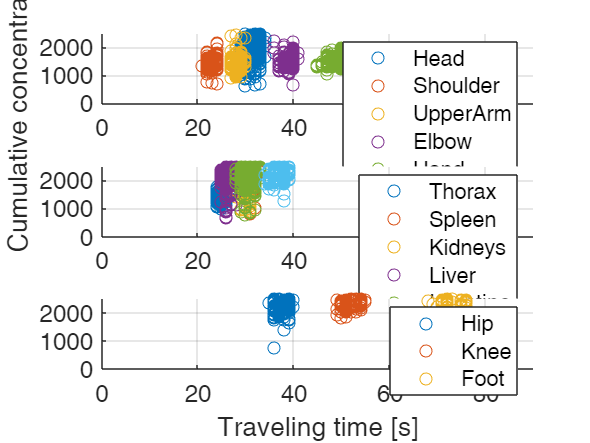

figure;

subplot 311
c=9;%Head
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)}); hold on;
%Upper Body
c=11;%Right Shoulder
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=15;%Right Upper Arm 
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=21;%Right Elbow
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=27;%Right Hand 
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
legend('Head','Shoulder','UpperArm','Elbow','Hand');
set(gca,'FontSize',font);
grid on;
axis([0 90 0 2500]);
ylabel('Cumulative concentration Level')

%Center Body
subplot 312
c=24; %Chest and back
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)}); hold on;
c=30; %Spleen
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=40;%Kidneys
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=36;%Liver
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=39;%Intestine
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=47;%Pelvis
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
set(gca,'FontSize',font);
grid on;
axis([0 90 0 2500]);

subplot 313
%Lower Body
c=49;%Left Hip
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});hold on;
c=54;%Left Knee
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=59;%Left Foot
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
legend('Hip','Knee','Foot');
set(gca,'FontSize',font);
grid on;
axis([0 90 0 2500]);
xlabel('Traveling time [s]');


%uncomment the  following two lines for saving the plot, these lines require R2020a or later
% f=gcf;
% exportgraphics(f,'delay_circuit_histogram.png','Resolution',300);

### Plotting the delay vs avg concentration per Body Region

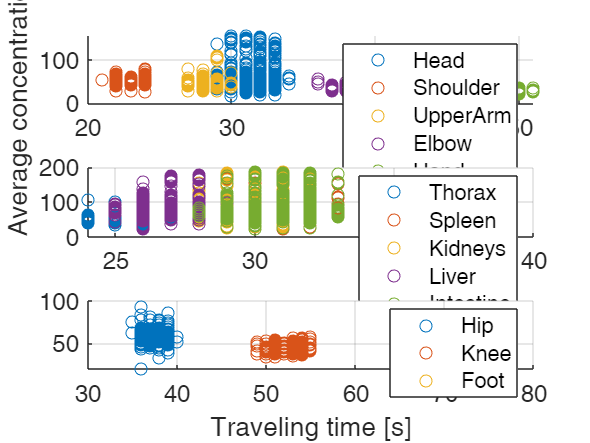

figure;

subplot 311
c=9;%Head
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)}); hold on;
%Upper Body
c=11;%Right Shoulder
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=15;%Right Upper Arm 
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=21;%Right Elbow
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=27;%Right Hand 
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
legend('Head','Shoulder','UpperArm','Elbow','Hand');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);
ylabel('Average concentration Level')

%Center Body
subplot 312
c=24; %Chest and back
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)}); hold on;
c=30; %Spleen
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=40;%Kidneys
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=36;%Liver
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=39;%Intestine
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=47;%Pelvis
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
legend('Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);

subplot 313
%Lower Body
c=49;%Left Hip
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});hold on;
c=54;%Left Knee
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
c=59;%Left Foot
scatter(delay_circuit{vessels_ID(c)},conc_avg_circuit{vessels_ID(c)});
legend('Hip','Knee','Foot');
set(gca,'FontSize',font);
grid on;
% axis([0 90 0 2500]);
xlabel('Traveling time [s]');


%uncomment the  following two lines for saving the plot, these lines require R2020a or later
% f=gcf;
% exportgraphics(f,'delay_circuit_histogram.png','Resolution',300);

### Plotting the delay vs cumul concentration 

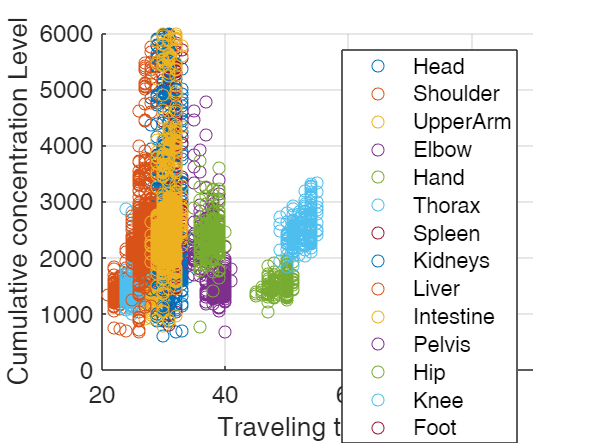

figure;

c=9;%Head
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)}); hold on;
%Upper Body
c=11;%Right Shoulder
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=15;%Right Upper Arm 
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=21;%Right Elbow
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=27;%Right Hand 
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});

set(gca,'FontSize',font);
grid on;

%Center Body
c=24; %Chest and back
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)}); hold on;
c=30; %Spleen
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=40;%Kidneys
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=36;%Liver
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=39;%Intestine
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=47;%Pelvis
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});


%Lower Body
c=49;%Left Hip
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});hold on;
c=54;%Left Knee
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});
c=59;%Left Foot
scatter(delay_circuit{vessels_ID(c)},conc_cumul_circuit{vessels_ID(c)});

legend('Head','Shoulder','UpperArm','Elbow','Hand','Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis','Hip','Knee','Foot');
set(gca,'FontSize',font);
grid on;
axis([20 90 0 6000]);
xlabel('Traveling time [s]')
ylabel('Cumulative concentration Level');


%uncomment the  following two lines for saving the plot, these lines require R2020a or later
% f=gcf;
% exportgraphics(f,'delay_circuit_histogram.png','Resolution',300);

## 3D Plots: histogram values vs travelling time and avg-concentration

### Visualizing data as an histogram in the Center Body

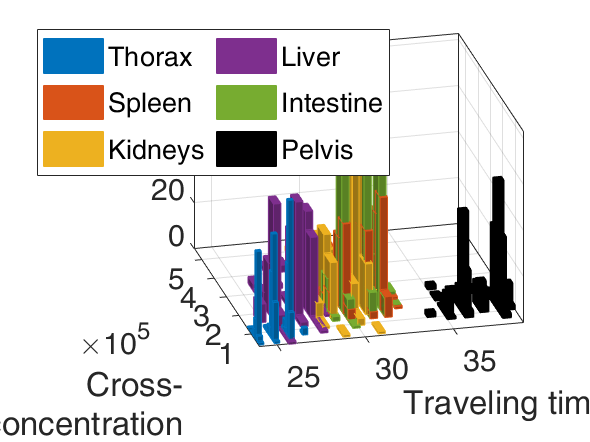

fontsize=15;
color_HEX = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#000000','#4DBEEE','#FF0000','#00FF00','#0000FF','#00FFFF','#FF00FF','#FFFF00','#000000','#A2142F'}; 
%list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html

%histogram resolution
bins=10;
totSampCirc=min([length(delay_Thorax) length(delay_Spleen) length(delay_Kidneys) ...
                               length(delay_Liver) length(delay_Intestine) length(delay_Pelvis)]);

%preparing data visualizing
%delay array
delay_center_body=horzcat(delay_Thorax(1:totSampCirc),delay_Spleen(1:totSampCirc),delay_Kidneys(1:totSampCirc), ...
                          delay_Liver(1:totSampCirc),delay_Intestine(1:totSampCirc),delay_Pelvis(1:totSampCirc));                   
%concentration array
conc_center_body=horzcat(conc_cross_Thorax(1:totSampCirc),conc_cross_Spleen(1:totSampCirc),conc_cross_Kidneys(1:totSampCirc),...
                    conc_cross_Liver(1:totSampCirc),conc_cross_Intestine(1:totSampCirc),conc_cross_Pelvis(1:totSampCirc));
%clustered data
dataCluster=horzcat(delay_center_body',conc_center_body')';

figure;
for i=1:6
    x1=(i-1)*totSampCirc+1;
    x2=x1+totSampCirc-1;
    h2=histogram2(dataCluster(1,x1:x2),dataCluster(2,x1:x2),bins,'FaceColor',color_HEX{i},'EdgeColor',color_HEX{i}); hold on;
end

ylabel({'Cross-','concentration'});
set(get(gca,'YLabel'),'Rotation',0)
xlabel('Traveling time [s]');
legend({'Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis'},'NumColumns',2);
legend('Position',[0.2555,0.60318,0.21429,0.32976]);
set(gca,'FontSize',fontsize)
view([-14 28]);


%uncomment the  following two lines for saving the plot, these lines require R2020a or later
% f=gcf;
% exportgraphics(f,'delay_circuit_histogram.png','Resolution',300);

### Visualizing data as an histogram in the complete Body

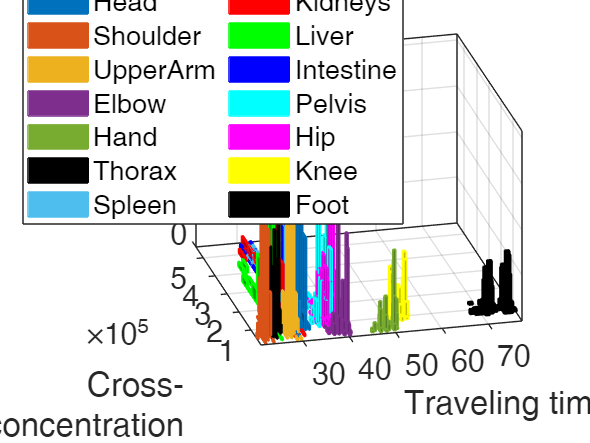

fontsize=15;
color_HEX = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#000000','#4DBEEE','#FF0000','#00FF00','#0000FF','#00FFFF','#FF00FF','#FFFF00','#000000','#A2142F'}; 
%list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html

%histogram resolution
bins=10;
totSampCirc=min([length(delay_Thorax) length(delay_Spleen) length(delay_Kidneys) ...
                               length(delay_Liver) length(delay_Intestine) length(delay_Pelvis)]);

%preparing data visualizing
%delay array
delay_full_body=horzcat(delay_Head(1:totSampCirc),delay_Shoulders(1:totSampCirc),delay_UpperArms(1:totSampCirc),delay_Elbows(1:totSampCirc),delay_Hands(1:totSampCirc), ...%Upper Body
                        delay_Thorax(1:totSampCirc),delay_Spleen(1:totSampCirc),delay_Kidneys(1:totSampCirc), ...%Center body
                        delay_Liver(1:totSampCirc),delay_Intestine(1:totSampCirc),delay_Pelvis(1:totSampCirc), ...
                        delay_Hips(1:totSampCirc),delay_Knees(1:totSampCirc),delay_Feet(1:totSampCirc)); %Lower Body
%concentration array
conc_full_body=horzcat(conc_cross_Head(1:totSampCirc),conc_cross_Shoulders(1:totSampCirc),conc_cross_UpperArms(1:totSampCirc),conc_cross_Elbows(1:totSampCirc),conc_cross_Hands(1:totSampCirc), ...%Upper Body
                       conc_cross_Thorax(1:totSampCirc),conc_cross_Spleen(1:totSampCirc),conc_cross_Kidneys(1:totSampCirc),...%Center body
                       conc_cross_Liver(1:totSampCirc),conc_cross_Intestine(1:totSampCirc),conc_cross_Pelvis(1:totSampCirc),...
                       conc_cross_Hips(1:totSampCirc),conc_cross_Knees(1:totSampCirc),conc_cross_Feet(1:totSampCirc)); ...%Lower Body
%clustered data
dataCluster=horzcat(delay_full_body',conc_full_body')';

figure;
for i=1:14
    x1=(i-1)*totSampCirc+1;
    x2=x1+totSampCirc-1;
    h2=histogram2(dataCluster(1,x1:x2),dataCluster(2,x1:x2),bins,'FaceColor',color_HEX{i},'EdgeColor',color_HEX{i}); hold on;
end

ylabel({'Cross-','concentration'});
set(get(gca,'YLabel'),'Rotation',0);
xlabel('Traveling time [s]');
legend({'Head','Shoulder','UpperArm','Elbow','Hand','Thorax','Spleen','Kidneys','Liver','Intestine','Pelvis','Hip','Knee','Foot'},'NumColumns',2);
legend('Position',[0.2555,0.60318,0.21429,0.32976])
set(gca,'FontSize',fontsize)
view([-14 28]);


%uncomment the  following two lines for saving the plot, these lines require R2020a or later
% f=gcf;
% exportgraphics(f,'delay_circuit_histogram.png','Resolution',300);
